## MAS 416 - Lecture 4 - Problem 1

clc; clear all; close all;

rho = 850; % kg/m^3


$$\begin{array}{l}
\beta =900\frac{N}{{\mathrm{mm}}^2 }\\
{10}^6 \;{\mathrm{mm}}^2 =m^2 \;\Longrightarrow \frac{{10}^6 \;{\mathrm{mm}}^2 }{m^2 }\\
\beta =900\frac{N}{{\mathrm{mm}}^2 }\cdot \frac{{10}^6 \;{\mathrm{mm}}^2 }{m^2 }=900\cdot {10}^6 \frac{N}{\mathrm{m²}}
\end{array}$$


beta = 900*10^6; % N/m^2
Cd = 0.55; % -


$$\begin{array}{l}
A_d =3\mathrm{mm²}\\
10⁶\;\mathrm{mm²}=\mathrm{m²}\Longrightarrow \frac{m^2 }{{10}^6 \;\mathrm{mm²}}\\
A_d =3\mathrm{mm²}\cdot \frac{m^2 }{{10}^6 \;\mathrm{mm²}}=3\cdot {10}^{-6} \;\mathrm{m²}
\end{array}$$


Ad = 3*10^-6; % m^2


$$\begin{array}{l}
V_2 =2000{\mathrm{cm}}^3 \\
{10}^6 \;{\mathrm{cm}}^3 =m^3 \Longrightarrow \frac{m^3 }{{10}^6 \;\mathrm{cm³}}\\
V_2 =2000{\mathrm{cm}}^3 \cdot \frac{m^3 }{{10}^6 \;\mathrm{cm³}}=2000\cdot {10}^{-6} {\;m}^3 
\end{array}$$


V_2 = 2000*10^-6; % m^3
p_2_init = 0; % Pa


$$\begin{array}{l}
p_{1_{\max } } =150\;\mathrm{bar}\\
1\;\mathrm{bar}={10}^5 \;\mathrm{Pa}\Longrightarrow \frac{10⁵\;\mathrm{Pa}}{\mathrm{bar}}\\
p_{1_{\max } } =150\;\mathrm{bar}\cdot \frac{10⁵\;\mathrm{Pa}}{\mathrm{bar}}=150\cdot {10}^5 \;\mathrm{bar}
\end{array}$$


p_1_max = 150 * 10^5; % Pa
t_ramp = 0.3; % s

simTime = 0.5; % s
t = 0; % s
dt = 10^-3; % Timestep resolution
idx = 1; % Counter

p1 = 0; % Pa
p2 = 0; % Pa

while t <= simTime
    % Generate ramp for p1
    if(t <= t_ramp)
    p1 = t/t_ramp * p_1_max; % If the time is between 0 and 0.3s, then create ramp
    else
    p1 = p_1_max; % When ramp time is completed, then the p1 pressure is constant
    end


Formula for $Q$:

   
$$Q_{P\rightarrow A} = C_d \cdot A_d \cdot SIGN\left(\sqrt{\Delta p}\right) \cdot \sqrt{\frac{2}{\rho} \cdot |(p_P - p_A)|}$$


    Q = Cd * Ad * sign(p1-p2)*sqrt(2/rho * abs(p1-p2)); % Numeric representation of orifice equation Q

    Formula for $\dot{p_2 }$:


$$\dot{p} = \frac{\beta}{V}\cdot \sum Q_i$$


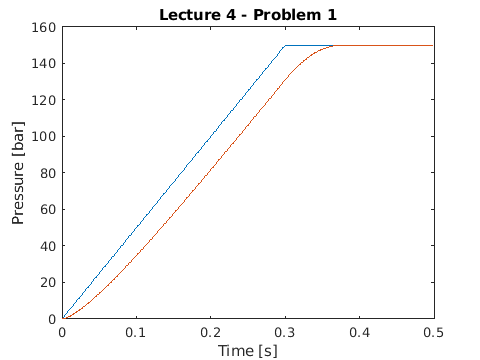

    % Equation for p2Dot is found on slide 8, lecture 4.
    p2Dot = (beta/V_2)*Q;

    % Logging
    timePlot(idx) = t;
    p1Plot(idx) = p1/10^5;
    p2Plot(idx) = p2/10^5;

    % Time integrate
    p2 = p2 + p2Dot * dt;

    % p2 can not be in vaccum
    if(p2<0)
        p2 = 0;
    end

    % Update variables
    idx = idx + 1;
    t = t + dt;
end

% Plot results
plot(timePlot, p1Plot)
hold on
plot(timePlot, p2Plot)
xlabel("Time [s]")
ylabel("Pressure [bar]")
title("Lecture 4 - Problem 1")